# LFPViewer for CNN ripples

The pipeline for SWR detection and manual curation is the following: 

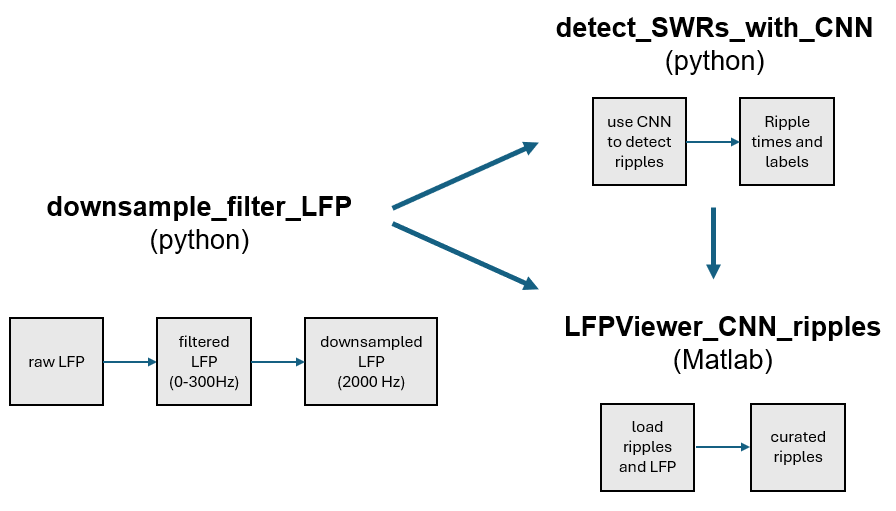

This script does the following: 

- Filter the LFP data to view sharp waves and ripples

- Load the SWR times and labels as detected from the CNN (or after the manual curation/buzcode detection for comparison)

- Run LFPViewer to manually curated the CNN-detected SWRs for 1 or 2 brain structures simultaneously

December 2023, Athina Apostolelli (adapted from Linus Meienberg)

## Set parameters

- cnn: determines if the CNN or if buzcode was used for SWR detection.

- downsampled_fs (if cnn == 1): determines which ripple file to use i.e., whether the CNN run with data downsampled at 1250- or 2000-Hz.

sessname = '128ch_concatenated_sessions';
animal = 'rEO_05';
channels = [107,106,83,109,108,86,105,89, 39,27,36,26,37,29,34,35]+1;
structures = ["left", "right"];
% structures = 'dHP';

cnn = 1; % 1 if using CNN for detection
curated = 1; % 1 if loading the curated file 
structure = 'dHP'; % if cnn = 0
downsampled_fs = 2000; % if cnn = 1 

% Maybe remove?
if cnn == 0  % buzcode used for detection
    region = structure;
end

if cnn == 1 && curated == 0
    lfp_path = 'C:\Users\RECORDING\Athina\Ripples\lfp_data';
    lfp_file = fullfile(lfp_path, animal, [sessname, '.amplifier_ds.lfp']);  % downsampled to 2000 Hz
    % lfp_path = 'I:\Dropbox (Yanik Lab)\Localization Manuscript 2024\RAT DATA\rEO_07\recording\session_1_2_230904_173347';
    lfp_file = fullfile(lfp_path, 'amplifier.lfp');
    ripple_path = 'C:\Users\RECORDING\Athina\Ripples\detection';
    ripple_file = fullfile(ripple_path, animal, strcat(string(downsampled_fs), 'Hz'), [sessname, '.ripples.mat']);

elseif cnn == 1 && curated == 1
    lfp_path = 'C:\Users\RECORDING\Athina\Ripples\lfp_data';
    lfp_file = fullfile(lfp_path, animal, [sessname, '.amplifier_ds.lfp']);  % downsampled to 2000 Hz
    % lfp_path = 'I:\Dropbox (Yanik Lab)\Localization Manuscript 2024\RAT DATA\rEO_07\recording\session_1_2_230904_173347';
    % lfp_file = fullfile(lfp_path, 'amplifier.lfp');
    ripple_path = 'C:\Users\RECORDING\Athina\Ripples\detection';
    ripple_path = 'C:\Users\RECORDING\Athina\Ripples\curated_ripples';
    ripple_file = fullfile(ripple_path, animal, sessname, 'curated_ripples.mat');

% TODO: maybe remove?
else
    lfp_path = 'C:\Users\RECORDING\Athina\Ripples\lfp_data\rTBY37\11_freely_behav_220630_142424';
    lfp_file = fullfile(lfp_path, 'amplifier_ds.lfp');  % downsampled to 2000 Hz
    ripple_path = 'C:\Users\RECORDING\Athina\Ripples\curated_ripples\rTBY37\11_freely_behav_220630_142424';
    ripple_file = fullfile(ripple_path, strcat('curated_ripples_', strcat(region, '.mat')));
end

## Import downsampled electrophysiological recording

For analysis of SWRs, the high frequency content of the LFP can be ignored. So the LFP that we will work with has been filtered at 0-300 Hz. Also the LFP has been downsampled to 2000 Hz. This filtered and downsampled LFP file is generated using the python script **downsample_filter_LFP. **

We import a subset of channels from the shanks implanted in intermediate and dorsal hippocampus, which we have manually inspected that they contain SWR events. Note that the ennumeration of channels in matlab is shifted by one with respect to the channel numbers in the channel map file. 

if cnn == 1
    if exist(lfp_file)
        % LFP = ImporterDAT_multi(lfp_file, 128, channels);
        LFP = ImporterDAT_multi(lfp_file, 16, [1:16]);  % filename, total_channels, channels
    else
        disp('The LFP file does not exist in this directory.');
        return
    end
else % TODO: maybe remove?
    if exist(lfp_file)
        if region == 'dHP'
            LFP = ImporterDAT_multi(lfp_file, 256, channels(1:8));
        else
            LFP = ImporterDAT_multi(lfp_file, 256, channels(9:16));
        end
    else
        disp('The LFP file does not exist in this directory.');
        return
    end
end

## Filter LFP for ripples and Hilbert transform

Design a digital band-pass filter for the frequency range from 130Hz to 245Hz to isolate ripple events. We are also calcutating the Hilbert transform that will be used for LFPViewer later on. 

d = designfilt('bandpassfir','FilterOrder',600,'StopbandFrequency1',125,'PassbandFrequency1',130,'PassbandFrequency2',245,'StopbandFrequency2',250,'SampleRate',2000);
% fvtool(d )
LFP_detrended = detrend(double(LFP')); % raw
LFP_filtered = filtfilt(d, LFP_detrended); % ripples
LFP_filtered_hilbert = abs(hilbert(LFP_filtered)); % hilbert transform

## Import ripples

The ripples have been detected with the CNN1D model from the rippl-AI repository or with Buzcode. 

if cnn == 1 && curated == 1
    if exist(ripple_file) 
        ripples = load(ripple_file);
        ripple_timestamps = ripples.ripple_timestamps;
        ripple_classes = ripples.ripple_classes;
    else
        error('The curated ripple file (CNN detection) does not exist in this directory.');
    end

elseif cnn == 1 && curated == 0 
    if exist(ripple_file)
        ripples = load(ripple_file);
        ripple_timestamps = ripples.spwr;
        ripple_classes = categorical(ripples.labels');
    else
        error('The ripple file (CNN detection) does not exist in this directory.');
    end
    
else
    if exist(ripple_file) 
        ripples = load(ripple_file);
        ripple_timestamps = ripples.ripple_timestamps;
        ripple_classes = ripples.ripple_classes;
    else 
        error('The ripple file (Buzcode detection) does not exist in this directory.');
    end
end

## Run LFPViewer 

We can use LFPViewer to visualize the resulting dataset and investigate the differences between the different detection methods.

Additionally, we can label some of the detected intervalls as true ripple events manually or remove some false positives. This can be useful in later steps of the ripple curation workflow.

The data for LFPViewer have 3 formats: 

- Raw LFP 

- Bandpass filtered 130-245 Hz for ripple detection 

- Hilbert transform 

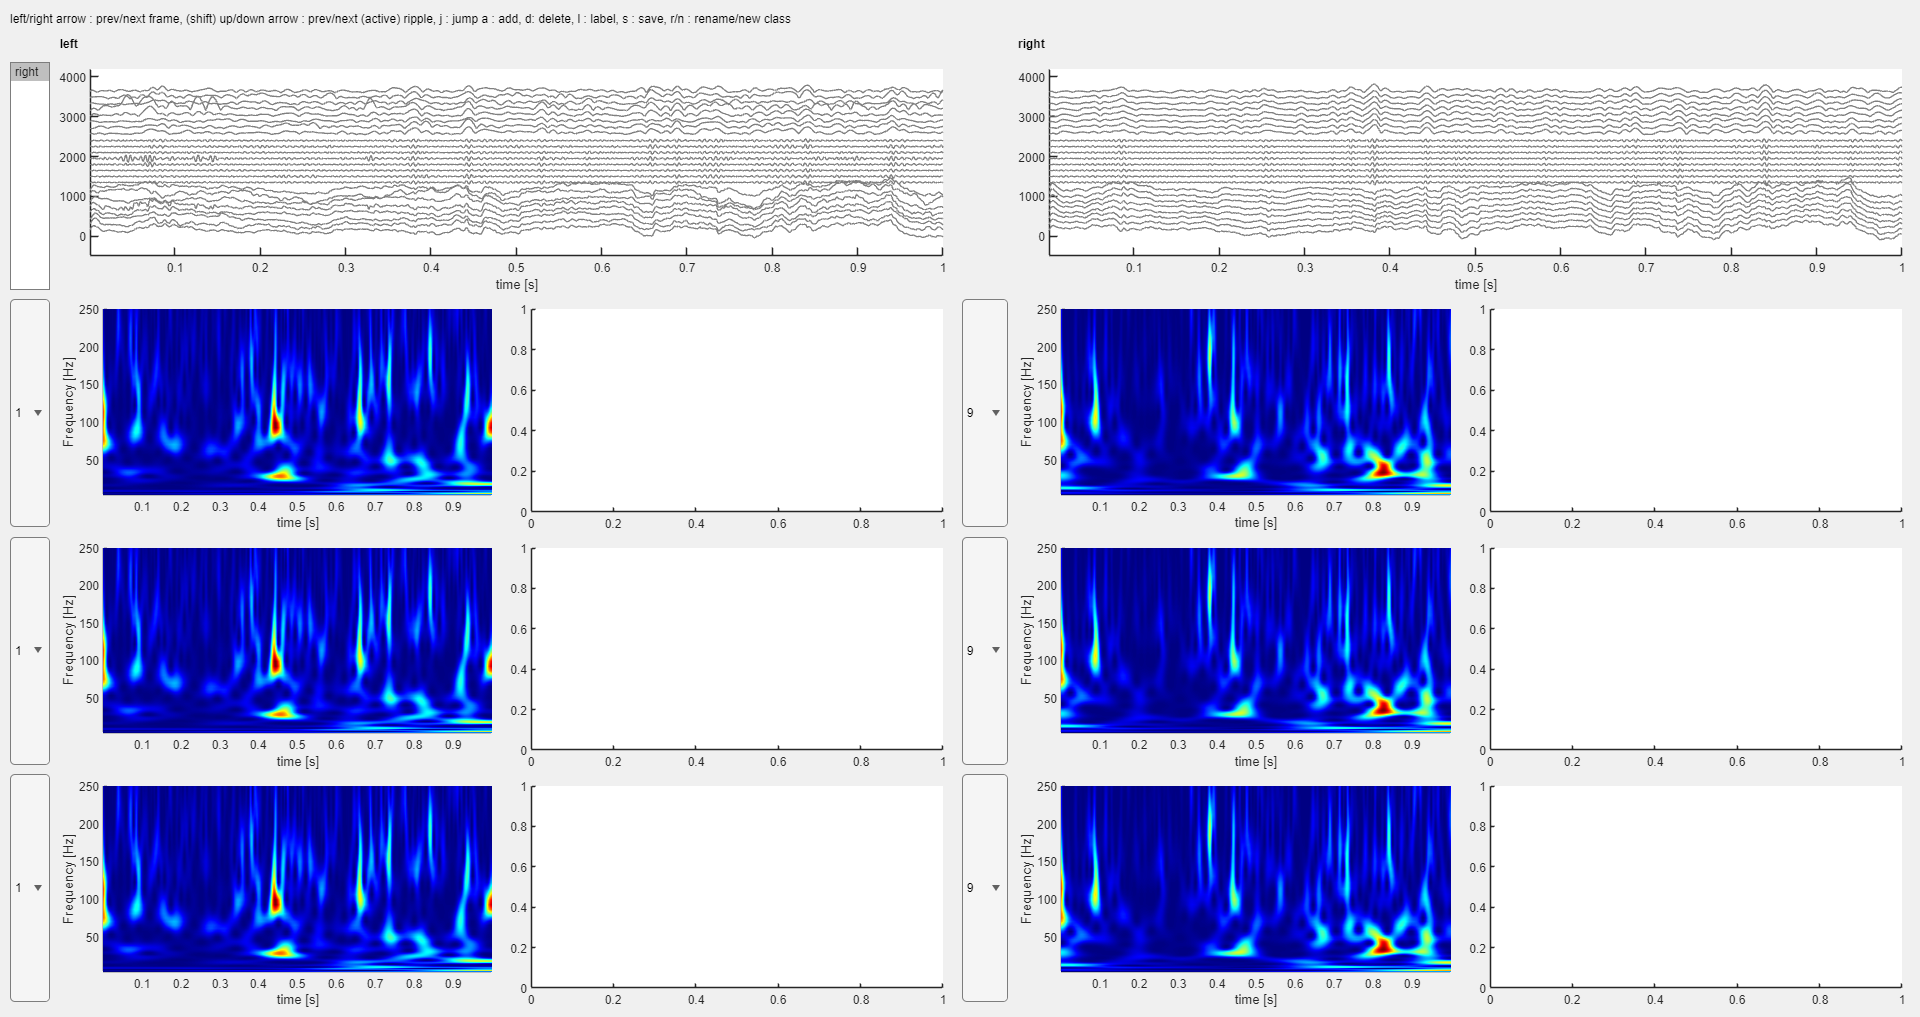

Click on left or right axis to select them before adding or deleting events.
The name of each type of event needs to contain the name of the associated structure.


centers = sum(ripple_timestamps,2)/2;

% 1 brain structure
% viewer = LFPViewer([(LFP_detrended./4) (LFP_filtered) (LFP_filtered_hilbert*4)], 2000, ripple_timestamps, centers, ripple_classes, false);

% 2 brain structures
viewer = LFPViewer_2views([(LFP_detrended./4) (LFP_filtered) (LFP_filtered_hilbert*4)], 2000, ripple_timestamps, centers, ripple_classes, structures, false);


% viewer = LFPViewer([(LFP_detrended./4) (LFP_filtered) (LFP_filtered_hilbert*4)], 2000, ripple_timestamps(ismember(ripple_classes,'dHP'),:), centers(ismember(ripple_classes,'dHP')), ripple_classes(ismember(ripple_classes,'dHP')), false, channels_toload);

## Conclusions on the comparison between CNN and buzcode/manual detection

The CNN seems to work very well when the data have been downsampled to either 1250 or 2000 Hz. Regardless of the threshold used for the detection, the events detected are approximately the same. If the threshold is set to 0.8, then we also capture most of the manually curated events. Specifically, the precision (% of true events that were detected) is >90% with both sampling frequencies. This was also confirmed by visual inspection on the LFPViewer. Nevertheless, manual curation after CNN detection is still needed.